# MATLAB을 활용한 AI 프로그래밍 - 충남대학교 김병관

- 한국전자파학회 2022 하계 전파교육 단기강좌 (8월 5일, 12일) 

- 문의사항: byungkwan.kim@cnu.ac.kr 

# 3. 일반적인 CNN 의 학습, 결과 분석하기

## [ Activity 1 ] 데이터의 양에 따라 학습 결과가 어떻게 되는지 확인 해 보세요.

- MATLAB의 partition 명령어는 데이터 저장소를 n 개로 나눕니다.  [ line 5 ]

- 현재 작성된 코드는 2분할, 즉 500개 데이터를 사용합니다.

- 예시 코드를 참고해서, 데이터의 양을 늘려가며 정확도를 분석 해 보세요.

## [ Activity 2 ] 필터의 개수 및 계층 수에 따라 학습 결과가 어떻게 되는지 확인 해 보세요.

- Conv - Normalization - Activation - Pooling - Dropout 의 묶음을 2개, 3개, 4개로 늘리면 어떻게 바뀌는 지 학습을 진행 해 보세요.

- Layer가 많을수록 학습 시간이 오래 걸리니 주의 해 주세요.

- 학습을 중지시키고 싶을 땐, MATLAB 원래 창에서 중지를 누르는게 빠르게 중지됩니다.

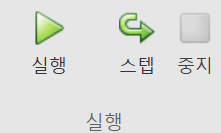

### 1) Import image data into MATLAB workspace

- 학습에 사용될 Image는 각각 폴더 내에 존재함. **(MATLAB 현재 폴더 확인)**

inputSize = [72 72 3];
numClasses = 10;
hf_radio = imageDatastore("./", "IncludeSubfolders",true,"FileExtensions",'.png','LabelSource','foldernames');

- **전체 1000개의 이미지 모두 활용**

- Dataset을 Train 및 Validation 으로 7:3 비율로 무작위로 분리

- Test용 Dataset이 필요한 경우, 아래 주석처리 된 코드로 분리 가능 (7:2:1)

hf_radio_shuffle = shuffle(hf_radio);
hf_radio_split = partition(hf_radio_shuffle, 2, 1);

- (참고용) 데이터저장소의 분할 및 결합을 통해, 임의의 데이터 수로 변환할 수 있습니다.

- 아래 주석된 코드는 250개 데이터 세트 4개로 분할후, 3개를 결합해 750개 데이터 세트로 만듭니다.

% hf_radio_split_1 = partition(hf_radio_shuffle, 4, 1);
% hf_radio_split_2 = partition(hf_radio_shuffle, 4, 2);
% hf_radio_split_3 = partition(hf_radio_shuffle, 4, 3);
% hf_radio_split_4 = partition(hf_radio_shuffle, 4, 4);
% hf_radio_split = combine(hf_radio_split_1, hf_radio_split_2, hf_radio_split_3)

[hf_radio_train, hf_radio_val] = splitEachLabel(hf_radio_split,0.7,'randomized');

### 2) Configure Neural Network using MATLAB Machine Learning Toolbox

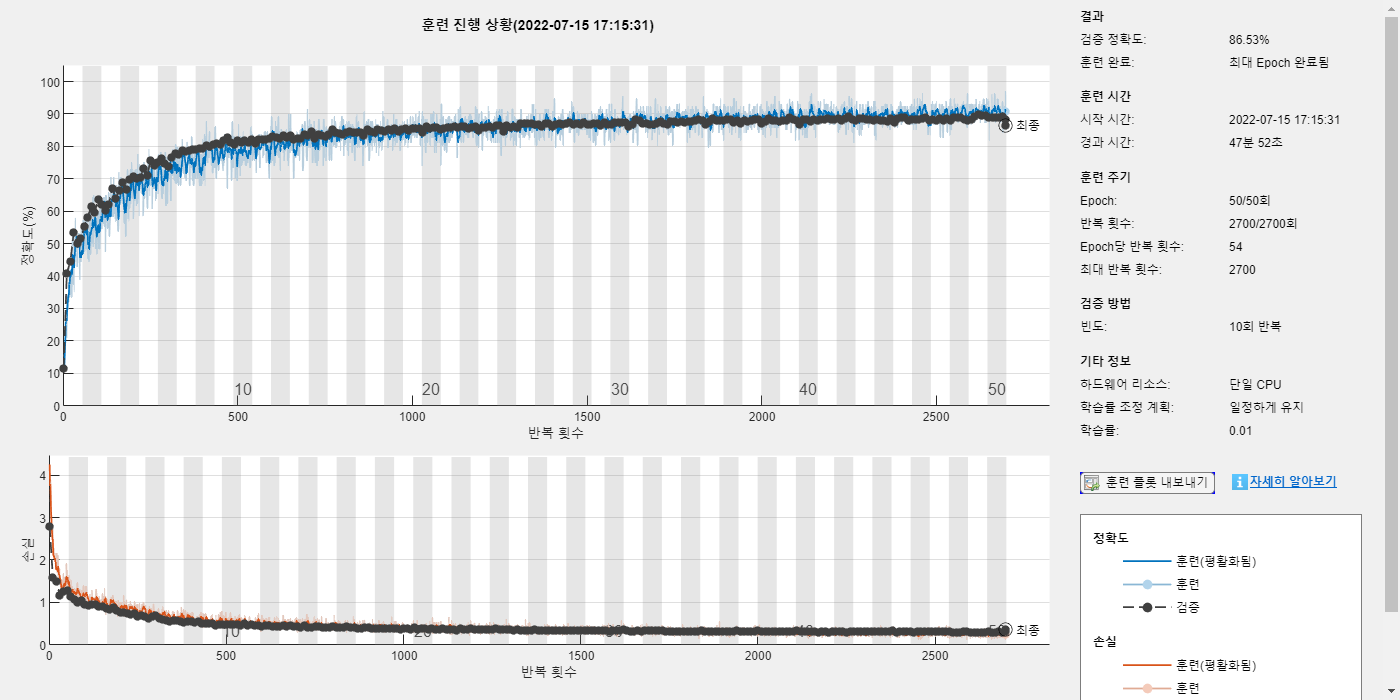

layers = [
    imageInputLayer(inputSize)

    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    dropoutLayer(0.5)


    convolution2dLayer(3,64,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,64,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    dropoutLayer(0.5)


Accuracy: 86.5333%


Training error: 7.3%


    fullyConnectedLayer(numClasses)

Validation error: 13.4667%


    softmaxLayer
    classificationLayer];

lgraph = layerGraph(layers);

#### MATLAB 제공 네트워크 분석기를 통한 파라미터 개수 평가 및 네트워크 구성 확인

analyzeNetwork(lgraph)

### 3) Convolutional Neural Network 학습을 위한 변수 설정 

- 확률적 경사하강법 알고리즘: SGDM, RMSProp, ADAM (강의자료 참고)

- Epoch: 학습 회수 / Learning Rate 등의 중요 hyperparameter 설정 가능

- 학습 연산 환경 (CPU/GPU) 설정 가능

- 단일 CPU로 학습시 약 45~50분 소요 (컴퓨터 성능에 따라 다름)

- Ref: [https://kr.mathworks.com/help/deeplearning/ref/trainingoptions.html](https://kr.mathworks.com/help/deeplearning/ref/trainingoptions.html)

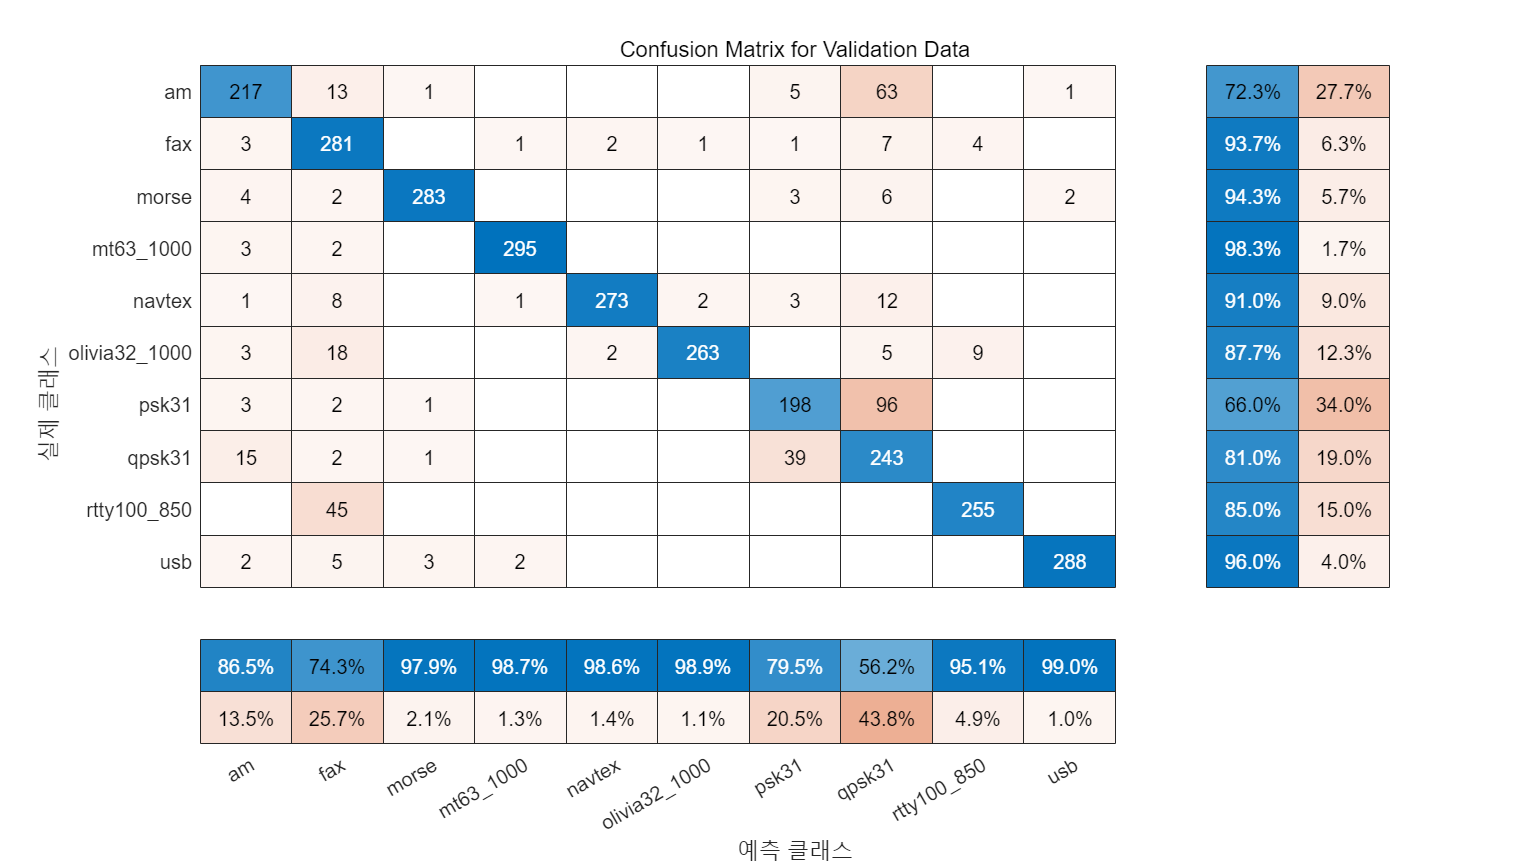

options = trainingOptions('sgdm', ...
    'MaxEpochs',50, ...
    'ValidationData',hf_radio_val, ...

    'ValidationFrequency',10, ...
    'Verbose',false, ...
    'Plots','training-progress', ...
    ExecutionEnvironment='gpu');

#### 구성된 네트워크의 학습 수행 명렁어

net = trainNetwork(hf_radio_train,layers,options);

### 4) 정확도 분석을 위한 Inference (추론) 수행 

- YPred 라는 변수에 Network 가 추론한 결과값이 저장되며,

- YValidation 및 YTrain은 학습을 위해 제공한 정답 Label이 들어 있음.

YPred = classify(net,hf_radio_val);
YValidation = hf_radio_val.Labels;
YTrain = hf_radio_train.Labels;

overall_precision = 0.8847

accuracy = mean(YPred == YValidation);
YTrainPred = classify(net,hf_radio_train);

overall_recall = 0.8653

validationError = mean(YPred ~= YValidation);

f1_score = 0.8749

trainError = mean(YTrainPred ~= YTrain);
disp("Accuracy: " + accuracy*100 + "%");
disp("Training error: " + trainError*100 + "%");
disp("Validation error: " + validationError*100 + "%");

### 5) Class 별 정확도 분석을 위한 Confusion Matrix 결과 확인 방법 

- confusionchart 명령어를 통한 분석 툴 제공

- Normalize 등의 옵션 설정 가능 

- [https://kr.mathworks.com/help/stats/confusionchart.html](https://kr.mathworks.com/help/stats/confusionchart.html)

cm = confusionchart(YValidation,YPred);
cm.Title = 'Confusion Matrix for Validation Data';
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';

#### -  Precision, Recall, F1 score 등의 계산은 아래와 같이 직접 수행해야 함 

- 혹은 confusion 명령어를 통해 False negative/positive 의 비율을 통해 계산해도 됨.

- Precision : True라고 분류한 것 중에서 실제로 True인 값의 비율 (TP/(TP+**FP**)) 

- Recall : 실제 True 데이타 중에서 모델이 True라고 예측한 비율 (TP/(TP+**FN**))

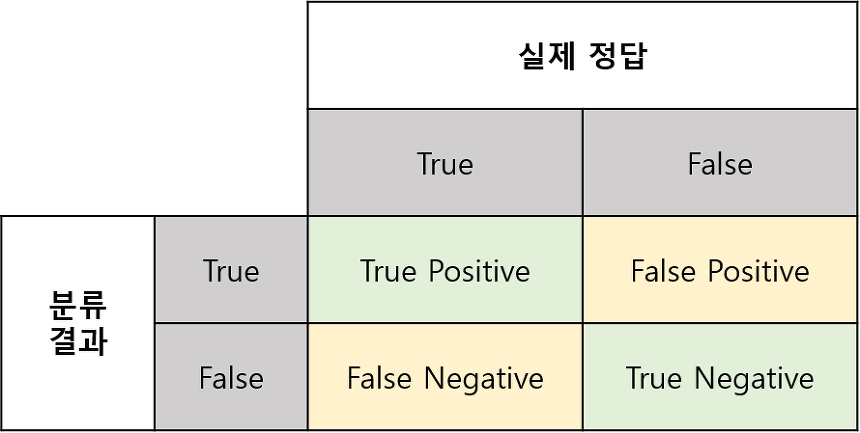

- Precision, Recall, F1 Score의 경우 Dataset 의 수가 불균형일 때 사용하는 대표적인 성능을 파악하는 수치

confusionMat = confusionmat(YValidation,YPred);
confusionMat = confusionMat';
precision = diag(confusionMat)./sum(confusionMat,2);
overall_precision = mean(precision)
recall= diag(confusionMat)./sum(confusionMat,1)';
overall_recall = mean(recall)
f1_score = 2*(overall_precision*overall_recall)/(overall_precision+overall_recall)